## GLENII fv4 Intro

In this  scrip we try to use MCMC method to fit parameter in GLENII model. The main part of Scrip is written according to example on [https://mjlaine.github.io/mcmcstat/ex/monodex.html](https://mjlaine.github.io/mcmcstat/ex/monodex.html)

## FDEWRB fv7 Intro

In this scrip, i adapt GLENII fv4 into FDEW

## Data Import

addpath

addpath(genpath('C:\Users\zhouquan\OneDrive\research\scrips\mcmcstat-2.1'))

clear variables from possible previous runs

clear data model options

create a data structure for the observations and control variables

data_name='p47';
selecting_curve='xy';

data_mode="mixed data";%data mode is "processed data" or "mixed data"
Selecting_Mode='discard'; %'discard','average'
if data_mode=="processed data"
    experiment_interval=30;
    min_length=40;
    time_scale=experiment_interval*(1:min_length);
    
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',data_name,'_',num2str(experiment_interval),'s.mat'])
    
    fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
    t=time_scale;
    a(1)=2.542e+05;%n142_30s
    a(2)=9.705e-05;
    a(3)=-1.391e+05;
    a(4)=-0.01086;
    
    Reserved_length=min_length;
    interceptive_experiment_MSD=[time_scale;1e-18*fun(a,time_scale)];
elseif data_mode=="mixed data"
    interceptive_experiment_MSD=[];
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\mixed data ',data_name,' ', Selecting_Mode,'.mat'])
    for i=1:length(t_mixMSD(1,:))
        if t_mixMSD(1,i)<=1200
            interceptive_experiment_MSD=[interceptive_experiment_MSD,[t_mixMSD(1,i);1e-18*t_mixMSD(2,i)]];

        end
    end
end
%now iterceptive_experiment_MSD contains all t data in line 1, and MSD data i 
data.xdata=interceptive_experiment_MSD(1,:);
data.ydata=interceptive_experiment_MSD(2,:);

and preview the data

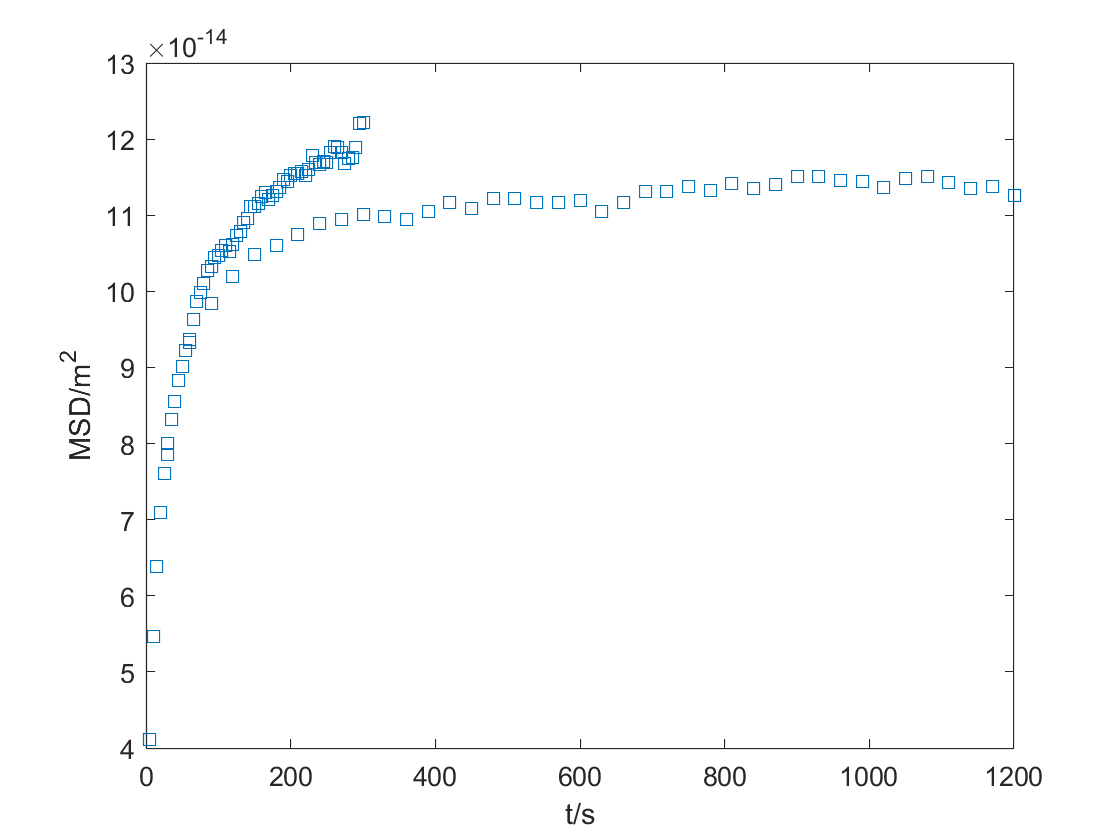

figure(1); clf
plot(data.xdata,data.ydata,'s');
xlim([0 1200]); xlabel('t/s'); ylabel('MSD/m^2');

## Model Import

defining function of GLENII model and its residual

modelfun= @(x,theta) FDEWRB_get_MSD(theta(1),theta(2),theta(3),x);
ssfun=@(theta,data) sum((data.ydata-modelfun(data.xdata,theta)).^2);

then just try to get the min residual

[tmin,ssmin]=fminsearch(ssfun,[5e-7;0.5;1e-14],[],data)

错误使用  ^  (line 51)
用于对矩阵求幂的维度不正确。请检查并确保矩阵为方阵并且幂为标量。要执行按元素矩阵求幂，请使用 '.^'。

出错 FDEWRB_get_MSD (line 5)
    sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);

出错 FDEWRB_para_select_fv7_MCMC (<a href="

n = length(data.xdata);
p = 2;
mse = ssmin/(n-p) % estimate for the error variance

The Jacobian matrix of the model function is easy to calculate so we use it to produce estimate of the covariance of theta. This can be used as the initial proposal covariance for the MCMC samples by option `options.qcov` below.

The Jacobian matrix here can not get Analytical expression, we can just use the definition of differential to calculate

J = [];
delta=1e-2;
for t = data.xdata
    temp_fun=FDEWRB_get_MSD(tmin(1),tmin(2),tmin(3),t);
    temp_J=[(FDEWRB_get_MSD(tmin(1)*(1+delta),tmin(2),tmin(3),t)-temp_fun)/tmin(1),(GLENII_get_MSD(tmin(1),tmin(2)*(1+delta),tmin(3),t)-temp_fun)/tmin(2),(GLENII_get_MSD(tmin(1),tmin(2),tmin(3)*(1+delta),t)-temp_fun)/tmin(3)]/delta;
    J=[J;temp_J];
end
tcov = inv(J'*J)*mse

## Input into MCMC

With it we set a positivity constraits for all of the parameters. 

Each parameter line can have up to 7 elements: 'name', initial_value, min_value, max_value, prior_mu, prior_sigma, and targetflag

params = {
    {'a', tmin(1), 0}
    {'\gamma', tmin(2), 0}
    {'K_\gamma', tmin(3), 0}
    };

Minimally we need to set `ssfun` for the sum of squares function and the initial estimate of the error variance `sigma2`.

model.ssfun  = ssfun;
model.sigma2 = mse; % (initial) error variance from residuals of the lsq fit
model.N = length(data.ydata);  % total number of observations
model.S20 = model.sigma2;      % prior mean for sigma2
model.N0  = 4;                 % prior accuracy for sigma2

Options structure

options.nsimu = 4000;
options.updatesigma = 1;
options.qcov = tcov; % covariance from the initial fit

mcmcrun

[res,chain,s2chain] = mcmcrun(model,data,params,options);

saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.05图像';
save([saving_location,'\data\mcmc result ',data_name],'chain','res',"s2chain")

## Plotting

parameter

figure(2); clf
mcmcplot(chain,[],res,'chainpanel');

parameter2

figure(3);clf
average_para=[mean(chain(:,1)),mean(chain(:,2)),mean(chain(:,3))]
err_para=[0,0,0]
name_para=["a","\gamma","K_\gamma"]
for i=1:3
    error_para(1,i)=(sum((chain(:,i)-average_para(i)).^2)/(length(chain(:,i))*(length(chain(:,i))-1)))^0.5;
end


error

figure(6); clf
mcmcplot(sqrt(s2chain),[],[],'hist')
title('Error std posterior')

% add prior distribution to the plot, if it was informative
if res.N0>0
  xl = xlim; xx = linspace(xl(1),xl(2));
  hold on
  plot(xx,invchi1pf(xx,res.N0,sqrt(res.S20)))
  hold off
  legend('posterior','prior')
end

GLENII & exp data

x = linspace(0,1200)';
figure(1)
hold on
plot(x,modelfun(x,mean(chain)),'-k')
hold off
legend({'data','model'},'Location','best')
xlabel('t/s')
ylabel('MSD/m^2')